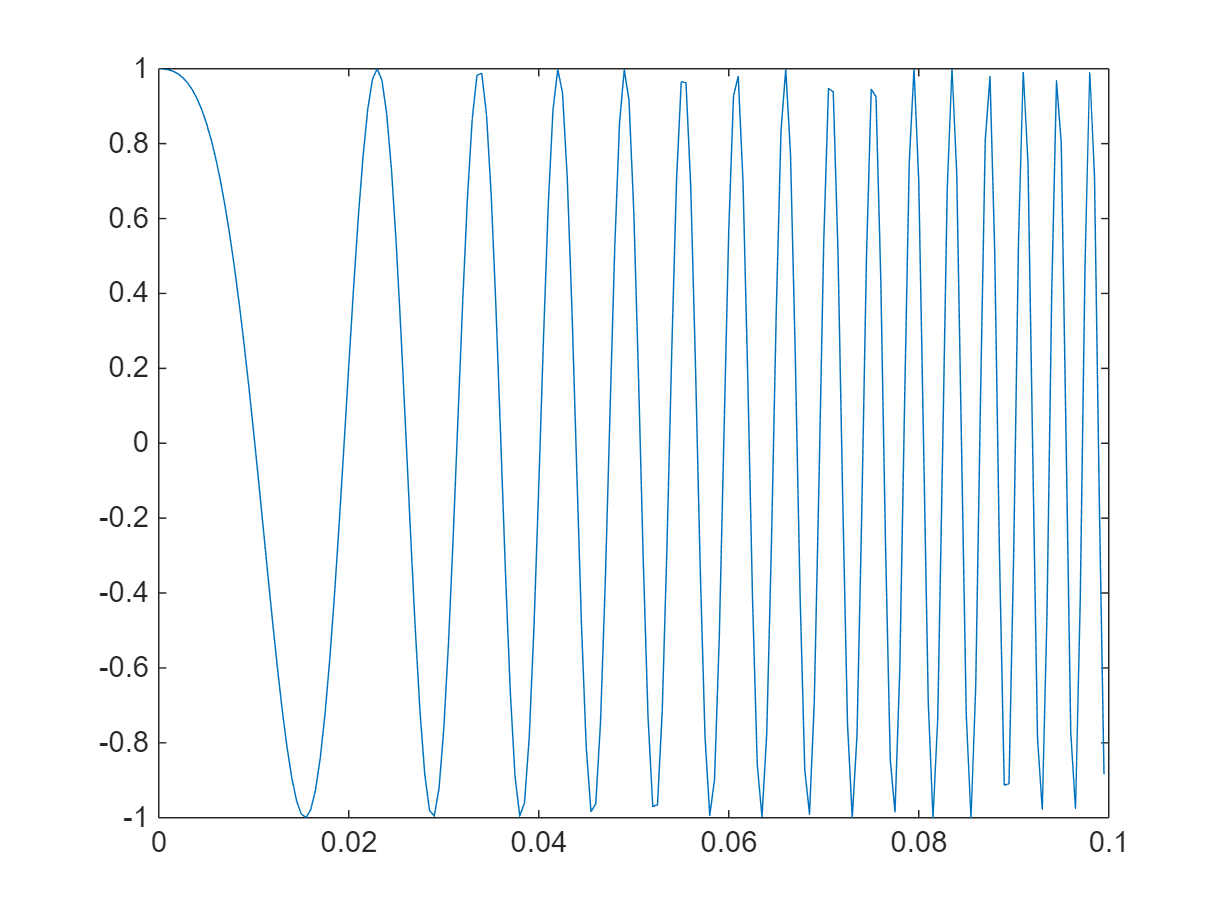

clear
fs=2000;
N=200;
x=zeros(1,500);
dt=1/fs;
t=(0:N-1)*dt;

f1=10;
f2=300;
yp = chirp(t,f1,t(end),f2);

plot(t,yp)

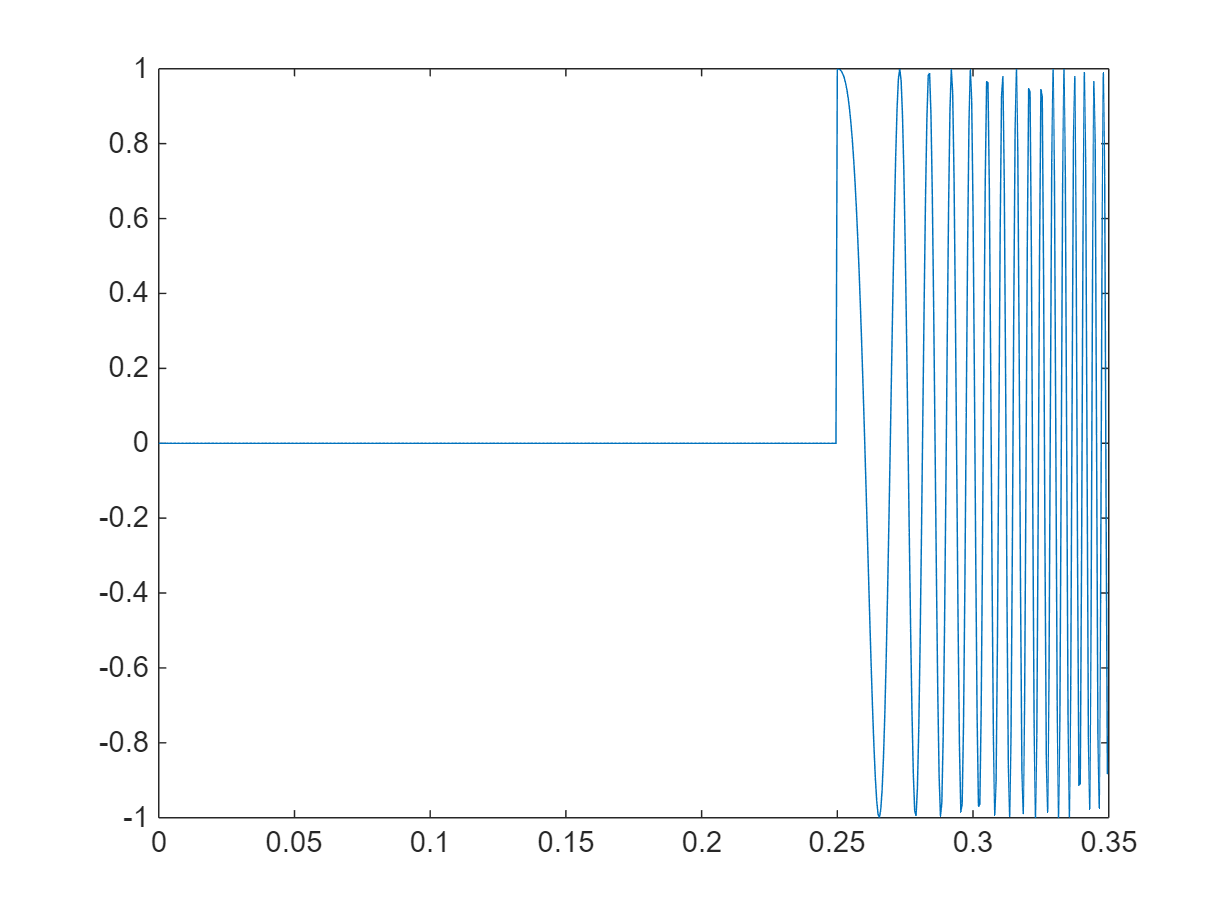


y=[x,yp];

N=length(y);
t=(0:N-1)*dt;
plot(t,y)

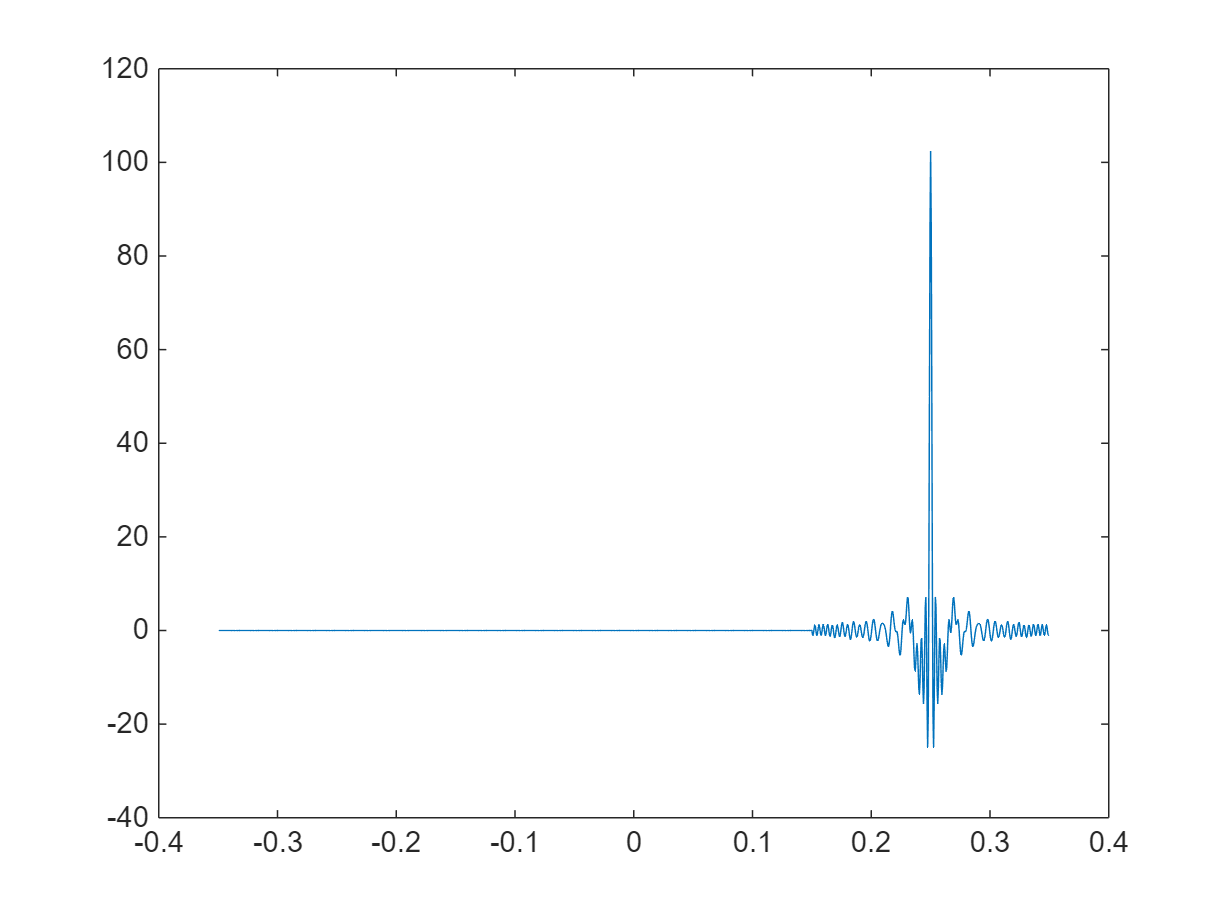


[yc,lag] = xcorr(y,yp);
tc = lag/fs;

plot(tc,yc)

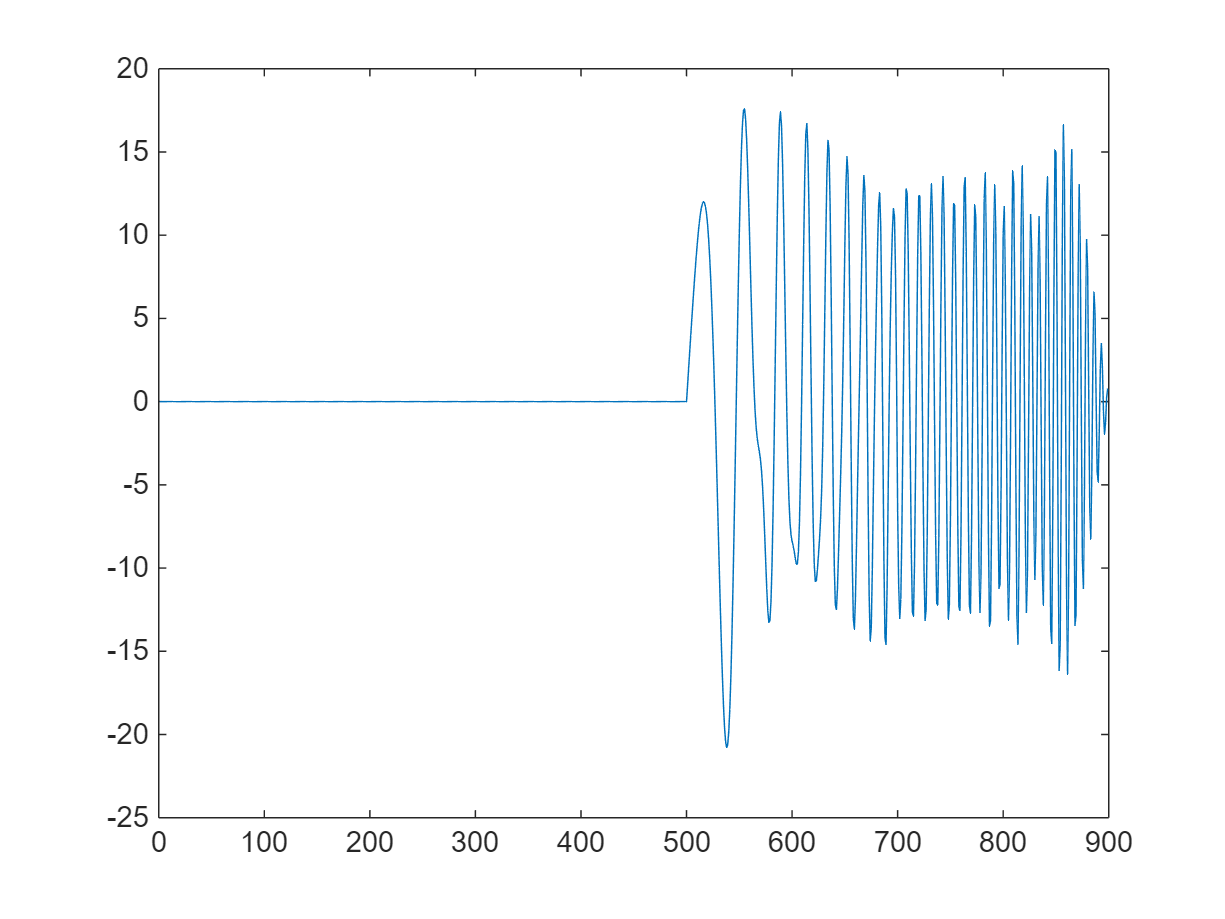


w=conv(yp,y);
plot(w)

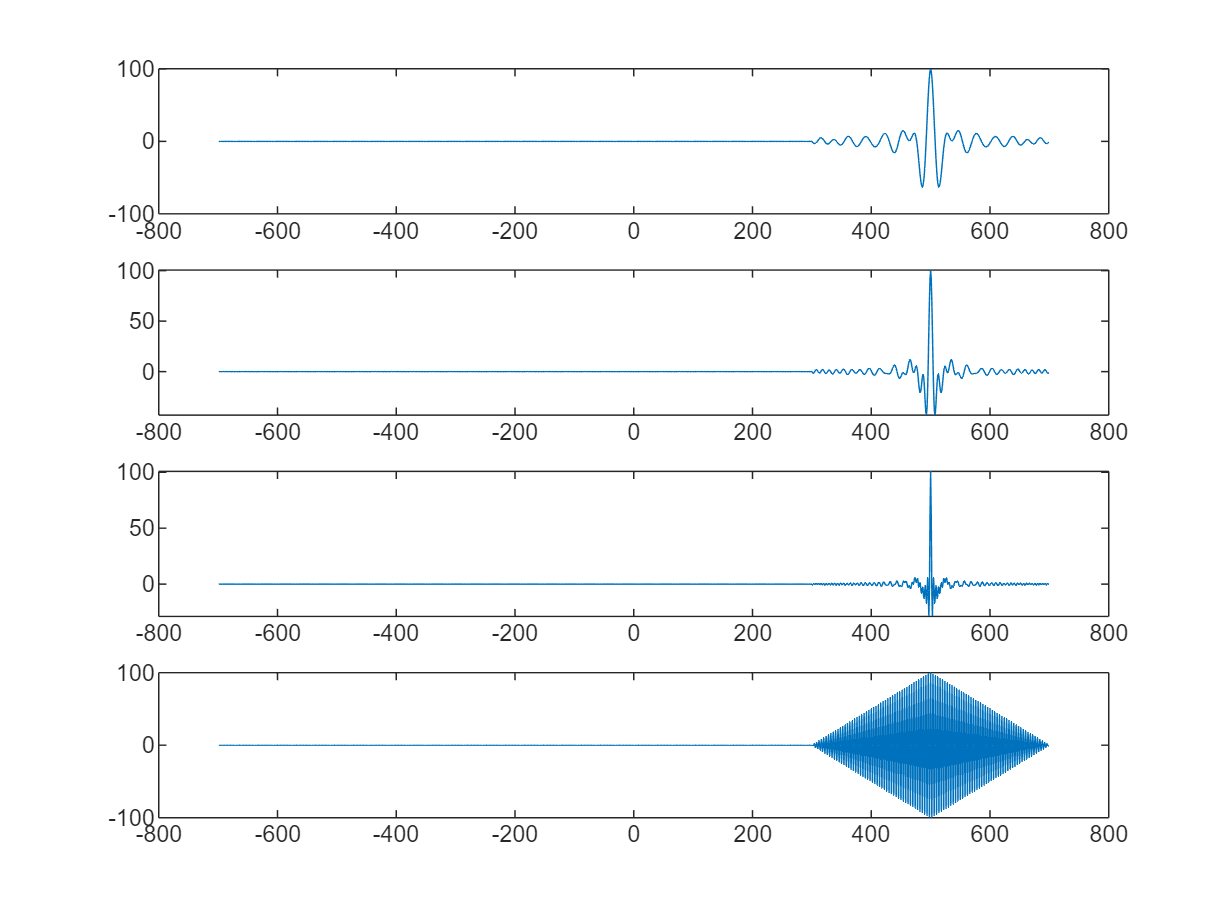

fs=2000;
N=200;
x=zeros(1,500);
dt=1/fs;
t=(0:N-1)*dt;



f1=30;
f2=[100,200,500];



x=zeros(1,500);
y=zeros(3,500+N);
yp=zeros(3,N);
figure
for i = 1:3
    yp(i,:) = chirp(t,f1,t(end),f2(i));
    y(i,501:end) = yp(i,:);
    [yc(i,:),lag(i,:)] = xcorr(y(i,:),yp(i,:));
    subplot(4,1,i)
    plot(lag(i,:),yc(i,:));hold on
end


yp2 = chirp(t,500,t(end),500);
y2=[zeros(1,500),yp2];
[yc2,lag2] = xcorr(y2,yp2);
subplot(4,1,4)
plot(lag2,yc2)
hold off;

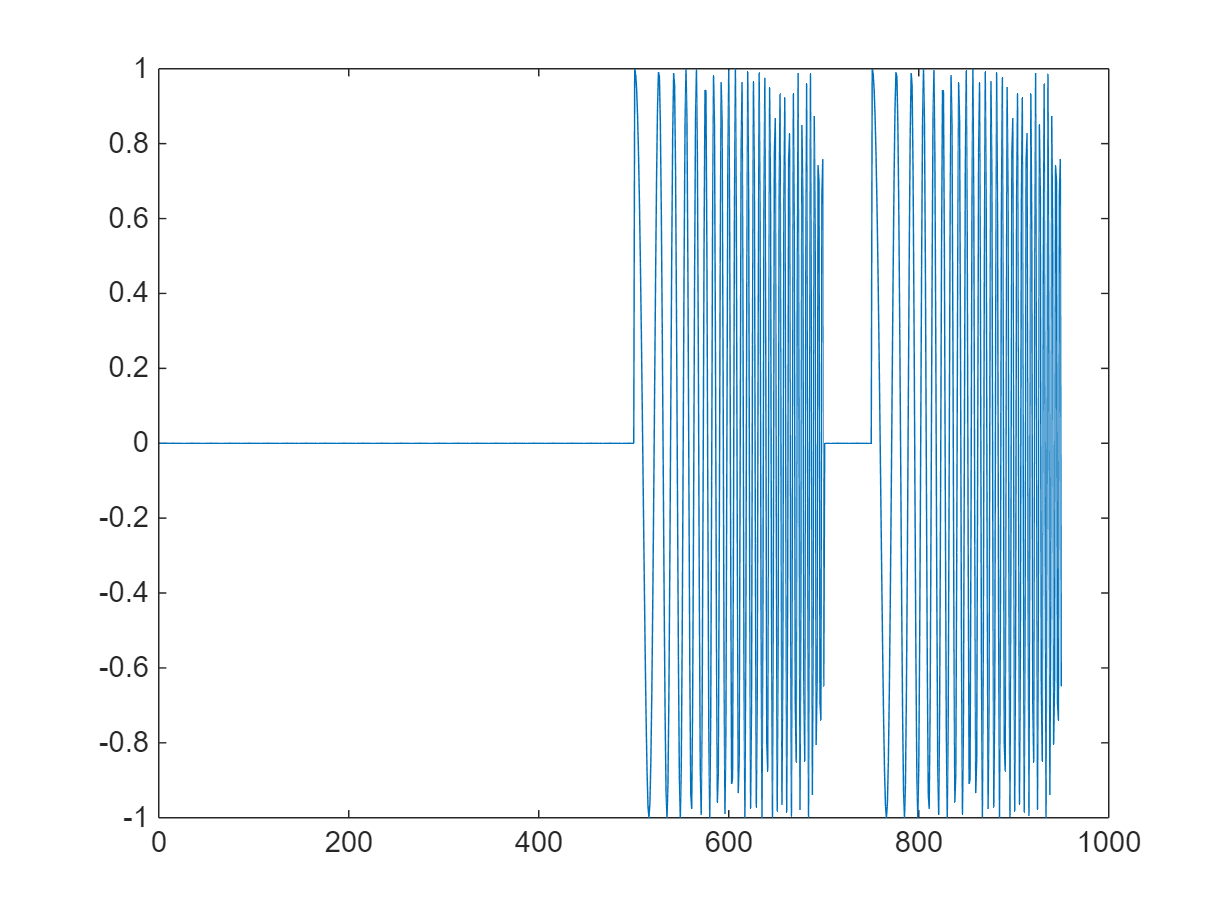

clear
fs=2000;
N=200;
x=zeros(1,500);
dt=1/fs;
t=(0:N-1)*dt;

f1=50;
f2=500;
yp = chirp(t,f1,t(end),f2);

yp=[zeros(1,500),yp,zeros(1,50),yp];
figure
plot(yp)

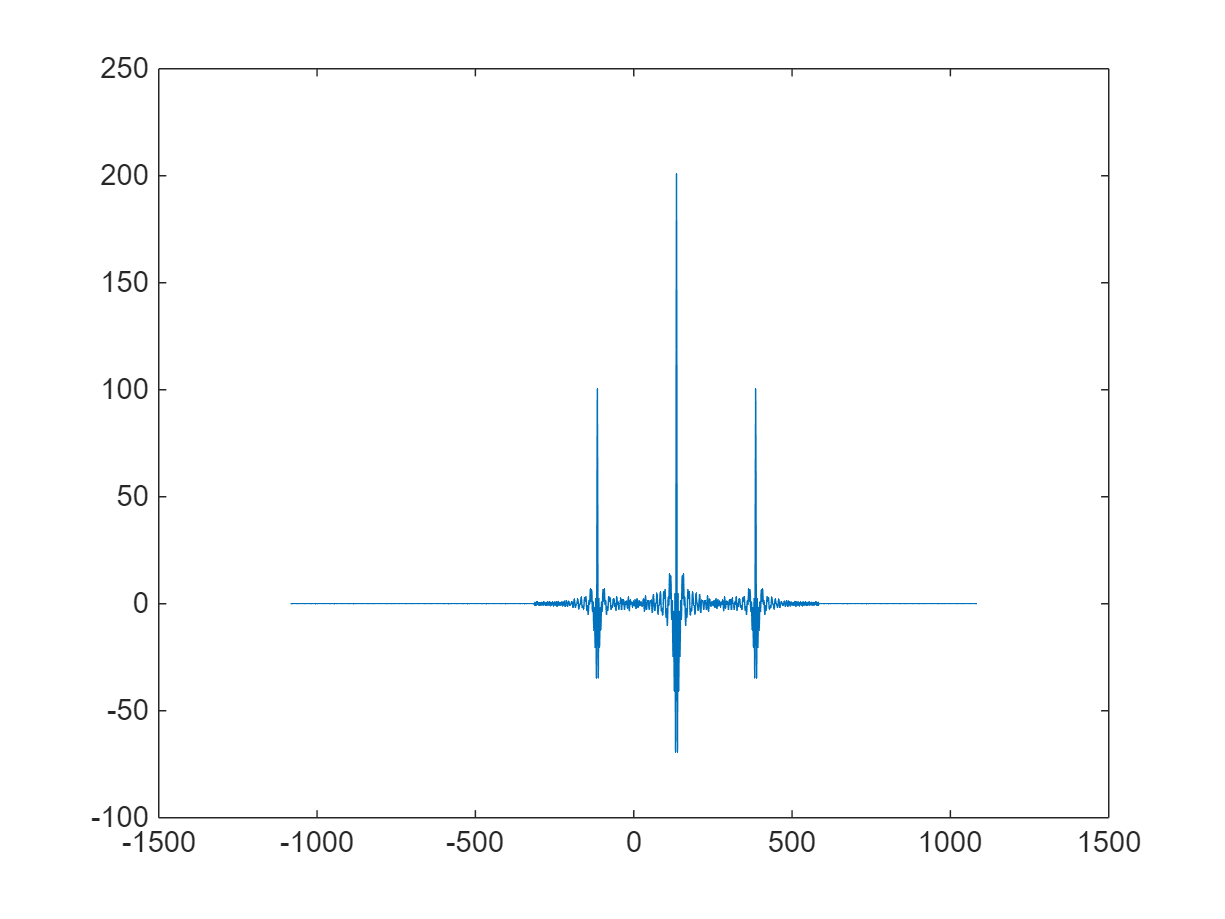

y=[zeros(1,135),yp];
[yc,lag] = xcorr(y,yp);
plot(lag,yc)

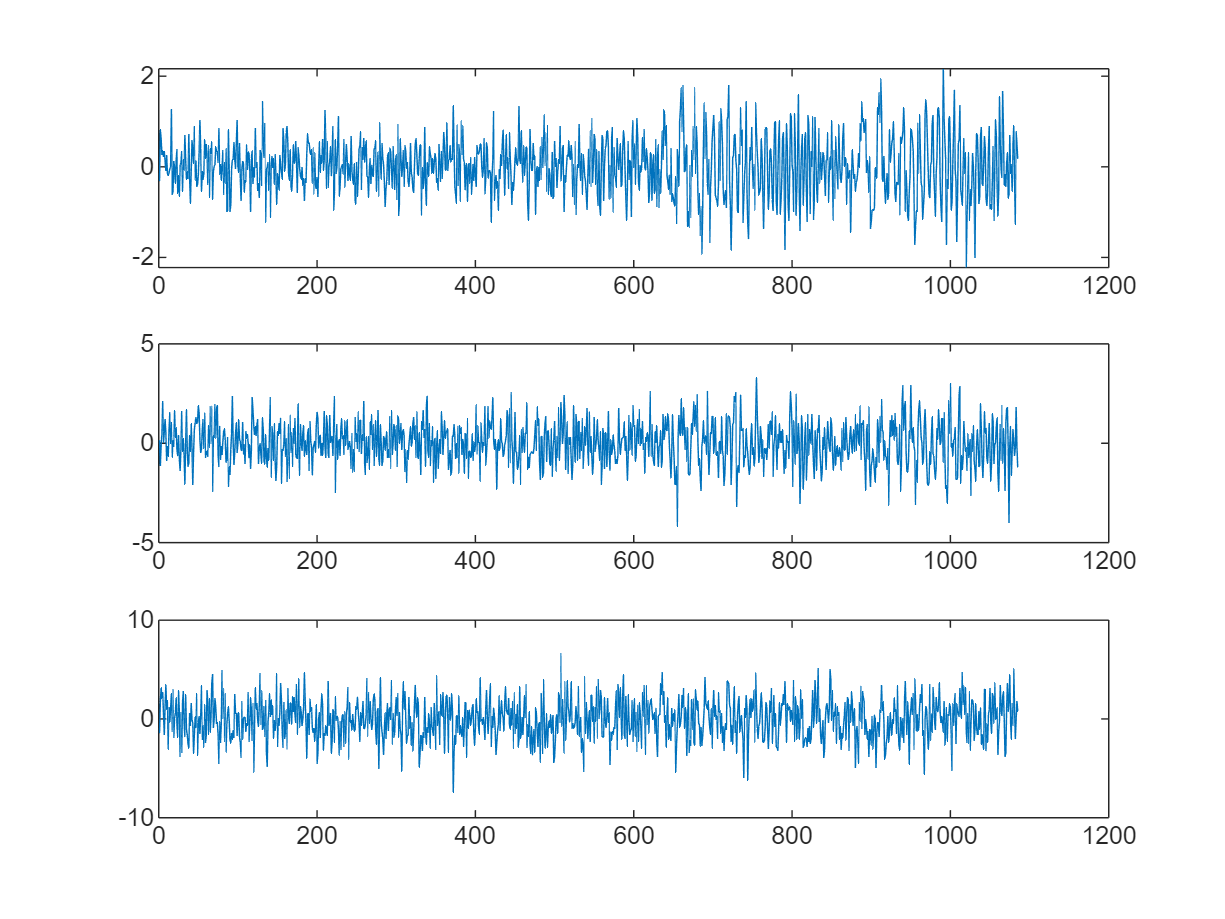

amp=[0.5,1,2];

figure
for i=1:3
noise(:,i) = amp(i)*randn(length(y),1);
yn(i,:)=y+noise(:,i)';
subplot(3,1,i)
plot(yn(i,:))
[yc(i,:),lag(i,:)] = xcorr(yn(i,:),yp);
end

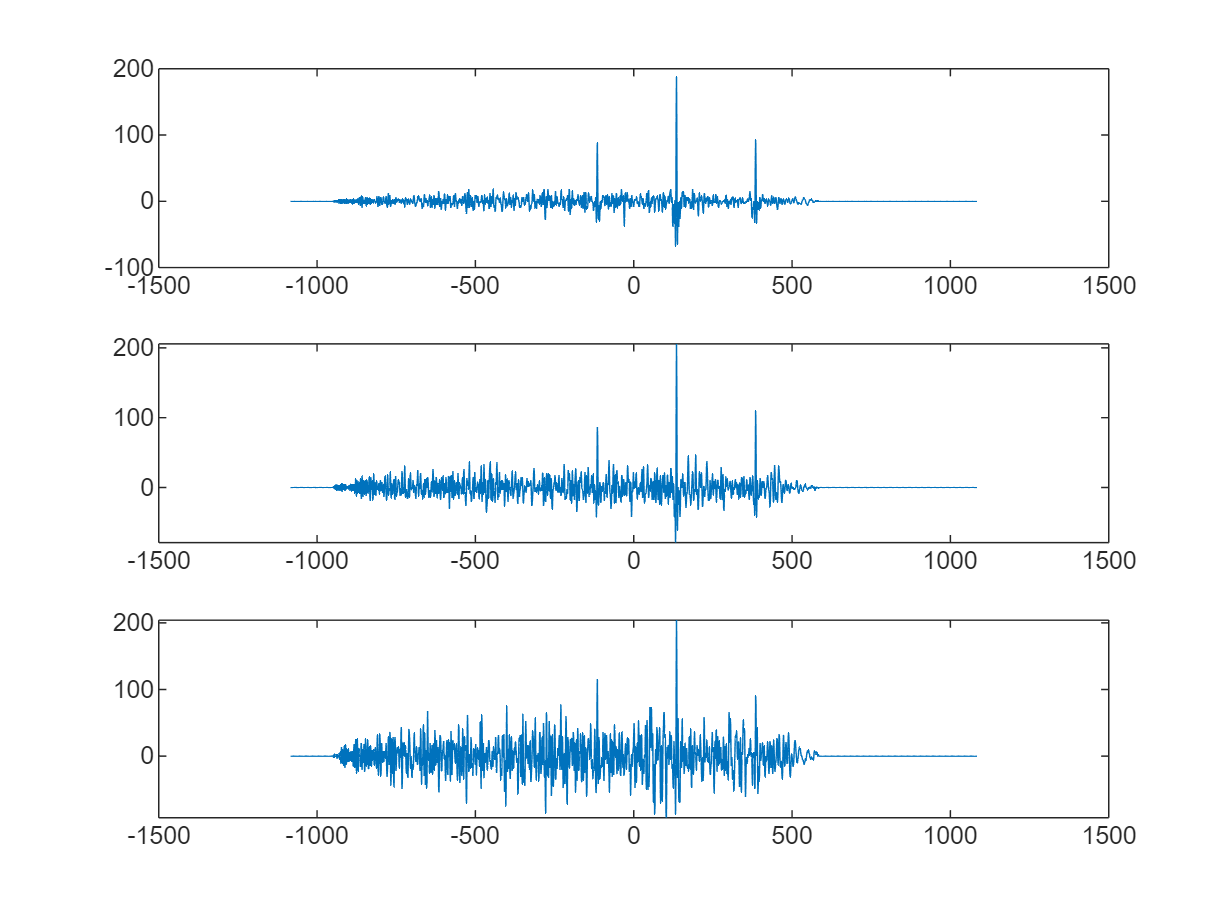


figure
for i=1:3
subplot(3,1,i)
plot(lag(i,:),yc(i,:))
end

## 2)

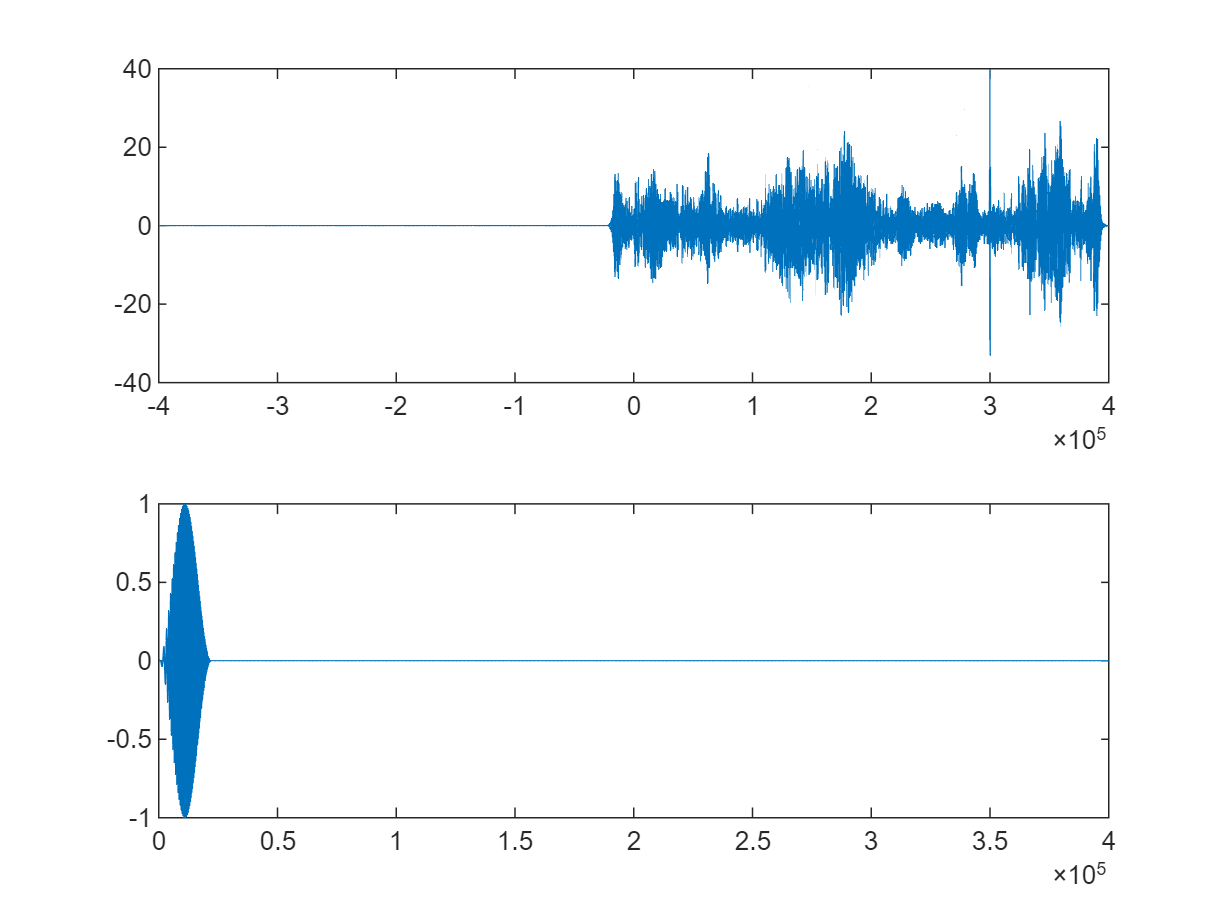

clear
[data,fs] = audioread("audio.wav");
% sound(data(:,2),fs)
load Pulse.mat
[r,lag]=xcorr(data(:,1),yp);
[r2,lag2]=xcorr(data(:,2),yp);
figure
subplot(2,1,1)
plot(lag,r)
subplot(2,1,2)
plot(lag2,r2)

N = length(data);           % Length of audio signal
yp_pad = [yp, zeros(1,N - length(yp))];  % Zero-padding of pulse
plot(yp_pad)

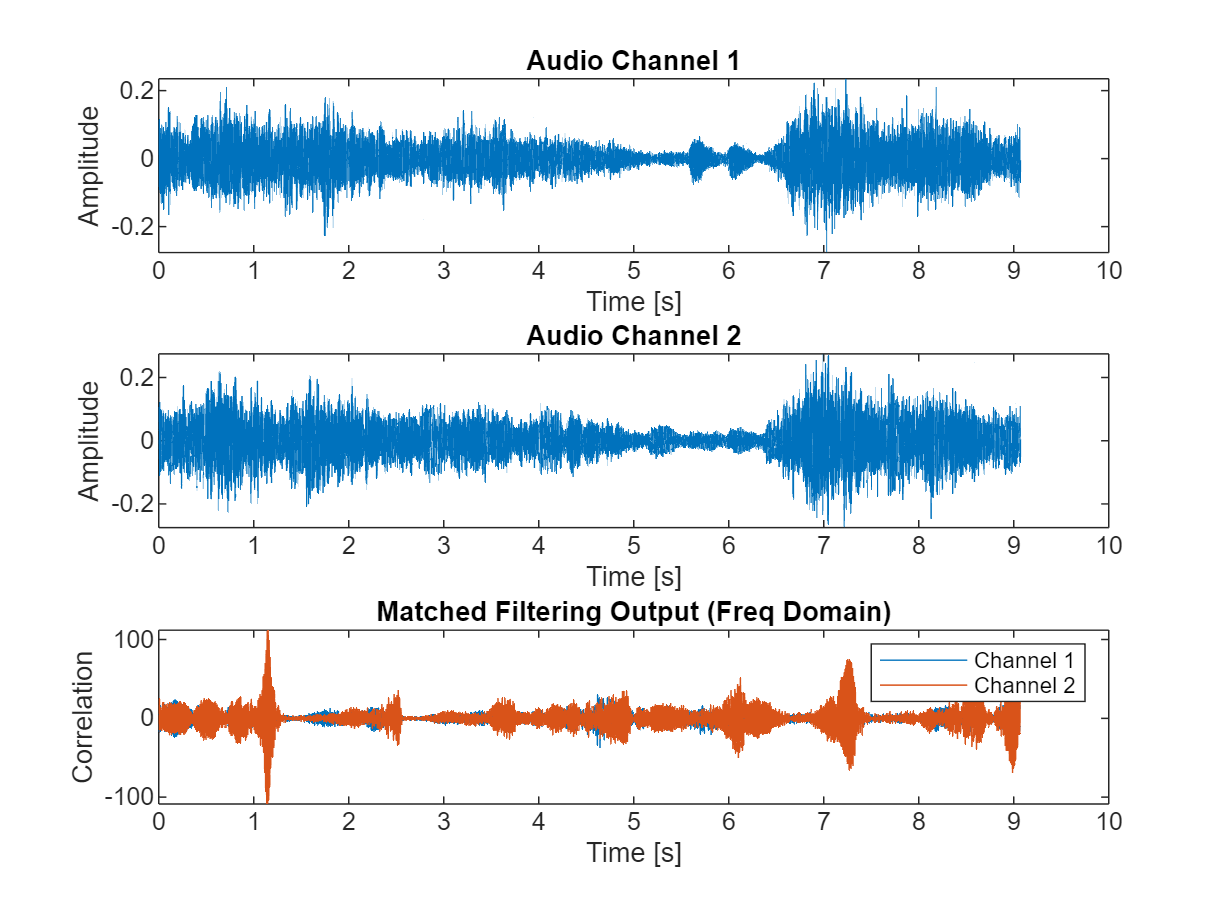

% Fourier transforms
data1_f = fft(data(:,1));
data2_f = fft(data(:,2));
yp_f = fft(yp_pad);

% Matched filtering (complex multiplication with conjugate)
yf1_inv = data1_f' .* conj(yp_f);
yf2_inv = data2_f' .* conj(yp_f);

% Inverse FFT to get time-domain matched filter output
matched1 = ifft(yf1_inv);
matched2 = ifft(yf2_inv);

% ---------------------------
% Plotting Results
% ---------------------------
figure
subplot(3,1,1)
plot((1:N)/fs, data(:,1))
title('Audio Channel 1')
xlabel('Time [s]'); ylabel('Amplitude')

subplot(3,1,2)
plot((1:N)/fs, data(:,2))
title('Audio Channel 2')
xlabel('Time [s]'); ylabel('Amplitude')

subplot(3,1,3)
plot((1:N)/fs, matched1)
hold on
plot((1:N)/fs, matched2)
title('Matched Filtering Output (Freq Domain)')
legend('Channel 1', 'Channel 2')
xlabel('Time [s]'); ylabel('Correlation')

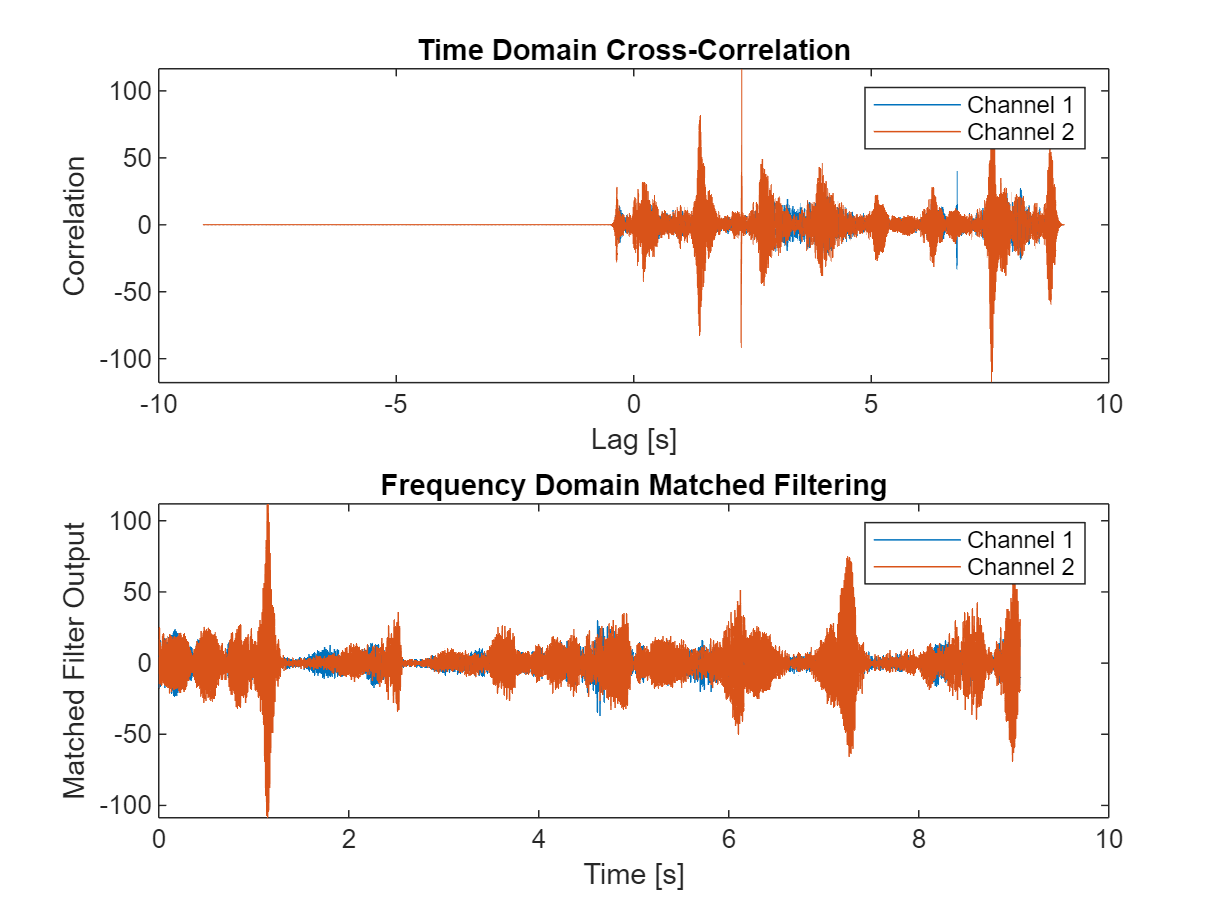


% ---------------------------
% Comparison Plot (Time-Domain vs Freq-Domain)
% ---------------------------
figure
subplot(2,1,1)
plot(lag/fs, r)
hold on
plot(lag2/fs, r2)
title('Time Domain Cross-Correlation')
legend('Channel 1', 'Channel 2')
xlabel('Lag [s]'); ylabel('Correlation')

subplot(2,1,2)
plot((1:N)/fs, matched1)
hold on
plot((1:N)/fs, matched2)
title('Frequency Domain Matched Filtering')
legend('Channel 1', 'Channel 2')
xlabel('Time [s]'); ylabel('Matched Filter Output')